clear all
close all
clc

A1=12;
A2=10;
A3=10;
A4=10;
A5=10;
A6=10;

q1=23.5;
q2=52.2;
q3=5;
q4=12;
q5=7;
q6=10;


L(1) = Link('revolute','d',A1,'alpha',pi/2,'a',0,'offset',0);
L(2) = Link('revolute','d',0,'alpha',pi/2,'a',0,'offset',pi/2); %eslabon 2 --> fila 2
L(3) = Link('prismatic','theta',0,'alpha',0,'a',0,'offset',A2+A3);
L(3).qlim = [0 2]; 
L(4) = Link('revolute','d',A4,'alpha',pi/2,'a',0,'offset',-pi/2)

 
L = 
 theta=q1, d=         12, a=          0, alpha=      1.571, offset=          0 (R,stdDH)
 theta=q2, d=          0, a=          0, alpha=      1.571, offset=      1.571 (R,stdDH)
 theta=          0, d=q3, a=          0, alpha=          0, offset=         20 (P,stdDH)
 theta=q4, d=         10, a=          0, alpha=      1.571, offset=     -1.571 (R,stdDH)


L(5) = Link('revolute','d',0,'alpha',0,'a',A5,'offset',pi/2)

 
L = 
 theta=q1, d=         12, a=          0, alpha=      1.571, offset=          0 (R,stdDH)
 theta=q2, d=          0, a=          0, alpha=      1.571, offset=      1.571 (R,stdDH)
 theta=          0, d=q3, a=          0, alpha=          0, offset=         20 (P,stdDH)
 theta=q4, d=         10, a=          0, alpha=      1.571, offset=     -1.571 (R,stdDH)
 theta=q5, d=          0, a=         10, alpha=          0, offset=      1.571 (R,stdDH)


L(6) = Link('revolute','d',0,'alpha',0,'a',A6,'offset',0)

 
L = 
 theta=q1, d=         12, a=          0, alpha=      1.571, offset=          0 (R,stdDH)
 theta=q2, d=          0, a=          0, alpha=      1.571, offset=      1.571 (R,stdDH)
 theta=          0, d=q3, a=          0, alpha=          0, offset=         20 (P,stdDH)
 theta=q4, d=         10, a=          0, alpha=      1.571, offset=     -1.571 (R,stdDH)
 theta=q5, d=          0, a=         10, alpha=          0, offset=      1.571 (R,stdDH)
 theta=q6, d=          0, a=         10, alpha=          0, offset=          0 (R,stdDH)


L

 
L = 
 theta=q1, d=         12, a=          0, alpha=      1.571, offset=          0 (R,stdDH)
 theta=q2, d=          0, a=          0, alpha=      1.571, offset=      1.571 (R,stdDH)
 theta=          0, d=q3, a=          0, alpha=          0, offset=         20 (P,stdDH)
 theta=q4, d=         10, a=          0, alpha=      1.571, offset=     -1.571 (R,stdDH)
 theta=q5, d=          0, a=         10, alpha=          0, offset=      1.571 (R,stdDH)
 theta=q6, d=          0, a=         10, alpha=          0, offset=          0 (R,stdDH)



%unir links 'eslabones'
robotesferico = SerialLink(L,'name','Angular')

 
robotesferico = 
 
Angular (6 axis, RRPRRR, stdDH, fastRNE)                         
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         12|          0|      1.571|          0|
|  2|         q2|          0|          0|      1.571|      1.571|
|  3|          0|         q3|          0|          0|         20|
|  4|         q4|         10|          0|      1.571|     -1.571|
|  5|         q5|          0|         10|          0|      1.571|
|  6|         q6|          0|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0    

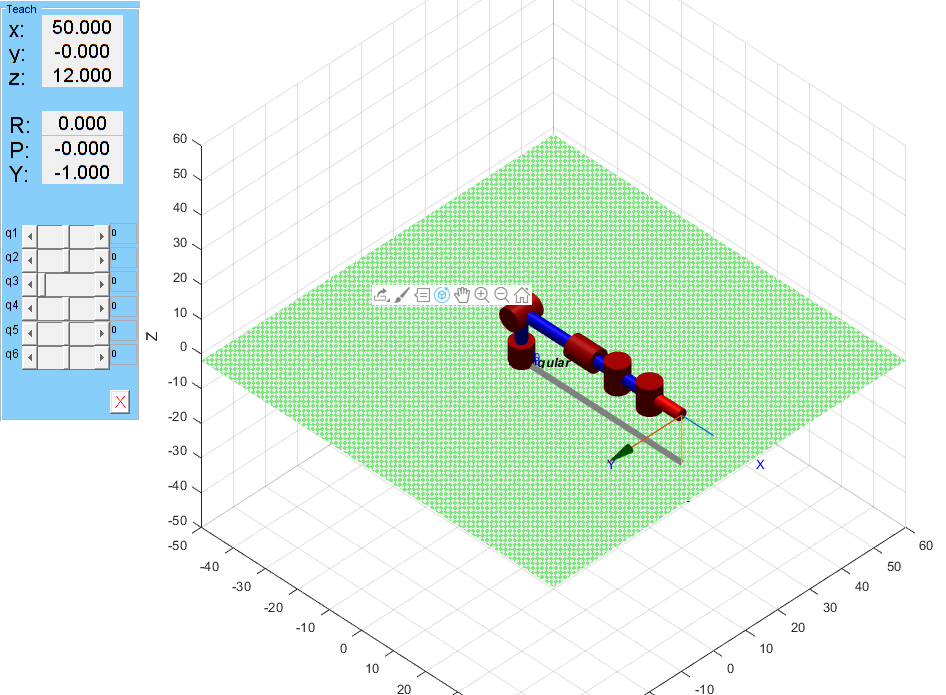


robotesferico.tool = transl(0,0,0);


q = [0 0 0 0 0 0];  % Ángulos de las articulaciones

% Define el espacio de trabajo (ajusta los valores según sea necesario)
limites_espacio_trabajo = [-50 60 -50 60 -2 60];

robotesferico.plot(q, 'workspace', limites_espacio_trabajo);

hold on 
trplot(eye(4),'rgb','length',1,'frame','0') % sistema coordenadas de la base 
axis([-50 60 -50 60 -50 60])% ajusta los ejes 
view(45, 40)% vista frente 
robotesferico.teach()


TZ0 = [1 0 0 0; 0 1 0 0; 0 0 1 A1; 0 0 0 1]

TZ0 =      1     0     0     0
     0     1     0     0
     0     0     1    12
     0     0     0     1


RZ0 = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0; 0 0 1 0; 0 0 0 1]

RZ0 =    -0.0619    0.9981         0         0
   -0.9981   -0.0619         0         0
         0         0    1.0000         0
         0         0         0    1.0000


TX1 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX1 = [1 0 0 0; 0 cos(pi/2) -sin(pi/2) 0; 0 sin(pi/2) cos(pi/2) 0; 0 0 0 1]

RX1 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


T01 =  TZ0*RZ0*TX1*RX1

T01 =    -0.0619    0.0000   -0.9981         0
   -0.9981   -0.0000    0.0619         0
         0    1.0000    0.0000   12.0000
         0         0         0    1.0000



TZ1 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TZ1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RZ1 = [cos(q2+(pi/2)) -sin(q2+(pi/2)) 0 0; sin(q2+(pi/2)) cos(q2+(pi/2)) 0 0; 0 0 1 0; 0 0 0 1]

RZ1 =    -0.9346    0.3558         0         0
   -0.3558   -0.9346         0         0
         0         0    1.0000         0
         0         0         0    1.0000


TX2 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX2 = [1 0 0 0; 0 cos(pi/2) -sin(pi/2) 0; 0 sin(pi/2) cos(pi/2) 0; 0 0 0 1]

RX2 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


T12 =  TZ1*RZ1*TX2*RX2

T12 =    -0.9346    0.0000   -0.3558         0
   -0.3558   -0.0000    0.9346         0
         0    1.0000    0.0000         0
         0         0         0    1.0000




TZ2 = [1 0 0 0; 0 1 0 0; 0 0 1 A2+A3; 0 0 0 1]

TZ2 =      1     0     0     0
     0     1     0     0
     0     0     1    20
     0     0     0     1


RZ2 = [cos(0) -sin(0) 0 0; sin(0) cos(0) 0 0; 0 0 1 0; 0 0 0 1]

RZ2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX3 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX3 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX3 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]

RX3 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T23 =  TZ2*RZ2*TX3*RX3

T23 =      1     0     0     0
     0     1     0     0
     0     0     1    20
     0     0     0     1



TZ3 = [1 0 0 0; 0 1 0 0; 0 0 1 A4; 0 0 0 1]

TZ3 =      1     0     0     0
     0     1     0     0
     0     0     1    10
     0     0     0     1


RZ3 = [cos(q4+(pi/2)) -sin(q4+(pi/2)) 0 0; sin(q4+(pi/2)) cos(q4+(pi/2)) 0 0; 0 0 1 0; 0 0 0 1]

RZ3 =     0.5366   -0.8439         0         0
    0.8439    0.5366         0         0
         0         0    1.0000         0
         0         0         0    1.0000


TX4 = [1 0 0 A4; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX4 =      1     0     0    10
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX4 = [1 0 0 0; 0 cos(pi/2) -sin(pi/2) 0; 0 sin(pi/2) cos(pi/2) 0; 0 0 0 1]

RX4 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


T34 =  TZ3*RZ3*TX4*RX4

T34 =     0.5366   -0.0000    0.8439    5.3657
    0.8439    0.0000   -0.5366    8.4385
         0    1.0000    0.0000   10.0000
         0         0         0    1.0000



TZ4 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TZ4 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RZ4 = [cos(q5+(pi/2)) -sin(q5+(pi/2)) 0 0; sin(q5+(pi/2)) cos(q5+(pi/2)) 0 0; 0 0 1 0; 0 0 0 1]

RZ4 =    -0.6570   -0.7539         0         0
    0.7539   -0.6570         0         0
         0         0    1.0000         0
         0         0         0    1.0000


TX5 = [1 0 0 A5; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX5 =      1     0     0    10
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX5 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]

RX5 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T45 =  TZ4*RZ4*TX5*RX5

T45 =    -0.6570   -0.7539         0   -6.5699
    0.7539   -0.6570         0    7.5390
         0         0    1.0000         0
         0         0         0    1.0000



TZ5 = [1 0 0 0; 0 1 0 0; 0 0 1 A6; 0 0 0 1]

TZ5 =      1     0     0     0
     0     1     0     0
     0     0     1    10
     0     0     0     1


RZ5 = [cos(q6) -sin(q6) 0 0; sin(q6) cos(q6) 0 0; 0 0 1 0; 0 0 0 1]

RZ5 =    -0.8391    0.5440         0         0
   -0.5440   -0.8391         0         0
         0         0    1.0000         0
         0         0         0    1.0000


TX6 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX6 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX6 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]

RX6 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T56 =  TZ5*RZ5*TX6*RX6

T56 =    -0.8391    0.5440         0         0
   -0.5440   -0.8391         0         0
         0         0    1.0000   10.0000
         0         0         0    1.0000



T03 = T01*T12*T23*T34*T45*T56

T03 =    -0.7859   -0.2020    0.5844    3.8879
    0.4337    0.4935    0.7539   22.7643
   -0.4407    0.8460   -0.3002   43.4264
         0         0         0    1.0000
